# PRACTICA 7: Compresi´on y denoising de im´agenes con la Wavelet Toolbox

## Ejercicio 1. Cargar y visualizar im´agenes Abrid un Live Script para los ejercicios: 

#### 1. Cargar una imagen usando load (debe estar en el ‘Current Directory’). Probar con lena gr, baboon (RGB) y Forest (indexada). 

#### 2. Observar las variables que aparecen en el ‘Workspace’. 

#### 3. Visualizarla con imshow. 

#### 4. Convertirla a double y visualizarla. 5 Guardar la imagen con un formato de imagen (JPG, PNG,...) con imwrite y abrirla con un visor.

% 1. Cargar una imagen usando load
lena = imread('lena_gr.tif');
baboon = imread('baboon.tiff');
forest = imread('forest.tif');

% 2. Observar las variables que aparecen en el ‘Workspace’
whos

  Name                        Size                  Bytes  Class     Attributes

  A1                        260x260                540800  double              
  A2                        256x256                524288  double              
  C                           1x266799            2134392  double              
  C_dec                       1x266799            2134392  double              
  C_umb                       1x266799            2134392  double              
  D1                        260x260                540800  double              
  Econs                       1x1                       8  double              
  Ew                          1x1                       8  double              
  Ew_values                   1x3                      24  double              
  H1                        256x256                524288  double              
  I_grises                  512x512               2097152  double              
  I_original                512x512    

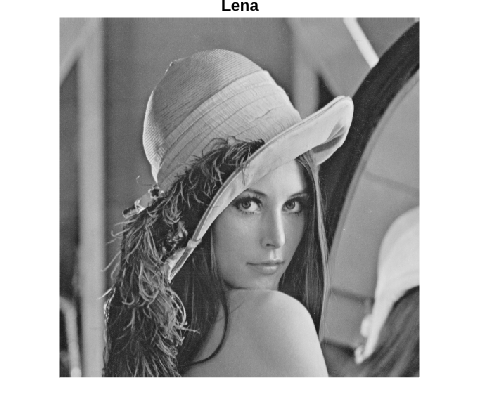


% 3. Visualizarla con imshow
figure, imshow(lena), title('Lena');

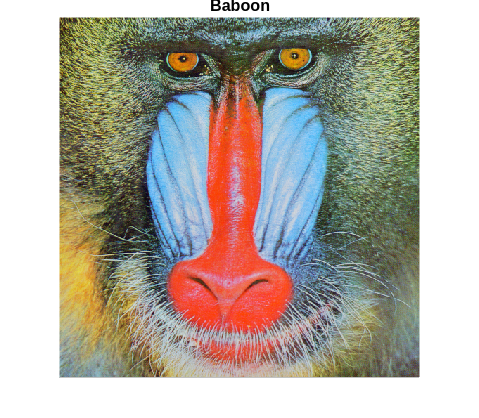

figure, imshow(baboon), title('Baboon');

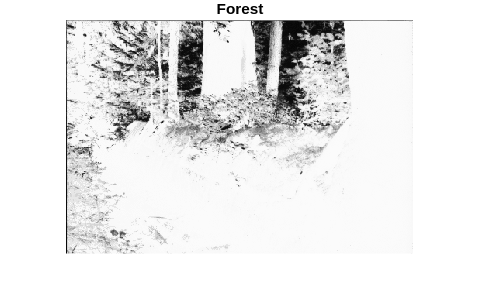

figure, imshow(forest), title('Forest');

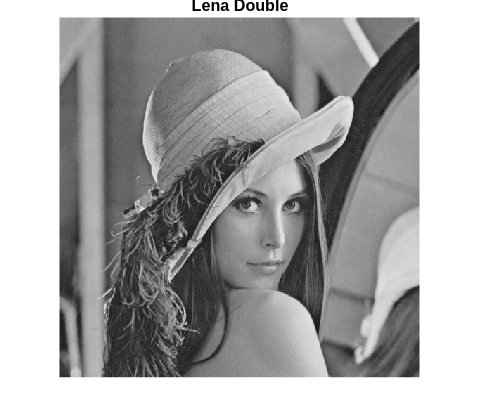


% 4. Convertirla a double y visualizarla
lena_double = im2double(lena);
baboon_double = im2double(baboon);
forest_double = im2double(forest);

figure, imshow(lena_double), title('Lena Double');

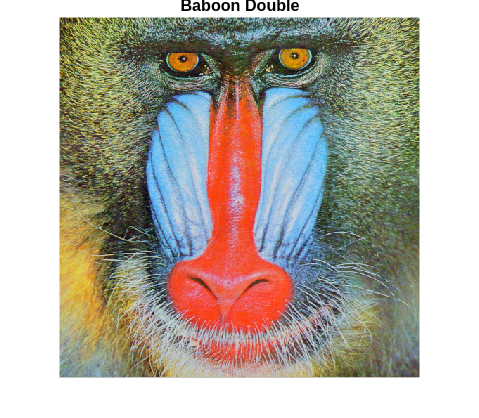

figure, imshow(baboon_double), title('Baboon Double');

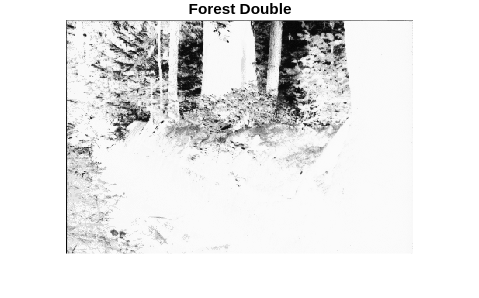

figure, imshow(forest_double), title('Forest Double');


% 5. Guardar la imagen con un formato de imagen (JPG, PNG,...) con imwrite
imwrite(lena_double, 'lena_double.jpg');
imwrite(baboon_double, 'baboon_double.jpg');
imwrite(forest_double, 'forest_double.jpg');

## Ejercicio 2. Descomposici´on wavelet de una imagen 

#### 1. Crear un script para analizar a nivel 1 una imagen (en escala de grises). 1 Cargar una imagen, por ejemplo barb.tif. 

#### 2 Calcular la transformada wavelet de nivel 1 con dwt2. >> [cA1,cH1,cV1,cD1] = dwt2(barb,’db2’); 

#### 3 Visualizar las matrices cA1, cH1, cV1 y cD1 (reescalar imshow(cA1,[])). 

#### 4 Obtener las aproximaciones y detalles del primer nivel. Ej: >> A1 = upcoef2(’a’,cA1,’db2’,1); 

#### 5 Visualizar las im´agenes A1, H1, V1, D1. 

#### 6 Reconstruir la imagen con idwt2 y mediante el an´alisis de multirresoluci´on A1+H1 + V1 + D1. 

#### 7 Visualizar las im´agenes reconstruidas. 

#### 8 Guardar la imagen en formato de imagen con imwrite.

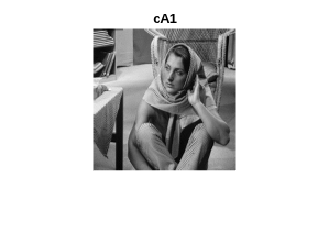

% 1. Cargar una imagen
barb = imread('barb.tif');

% 2. Calcular la transformada wavelet de nivel 1 con dwt2
[cA1,cH1,cV1,cD1] = dwt2(barb,'db2');

% 3. Visualizar las matrices cA1, cH1, cV1 y cD1
figure, imshow(cA1,[]), title('cA1');

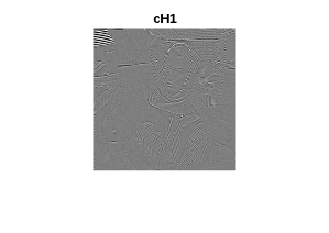

figure, imshow(cH1,[]), title('cH1');

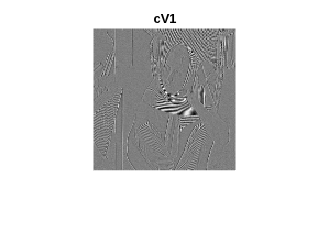

figure, imshow(cV1,[]), title('cV1');

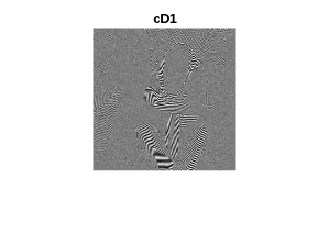

figure, imshow(cD1,[]), title('cD1');

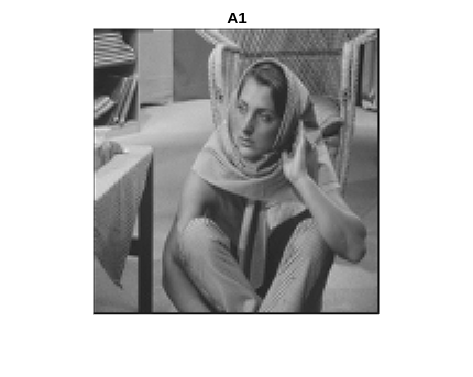


% 4. Obtener las aproximaciones y detalles del primer nivel
A1 = upcoef2('a',cA1,'db2',1);
H1 = upcoef2('h',cH1,'db2',1);
V1 = upcoef2('v',cV1,'db2',1);
D1 = upcoef2('d',cD1,'db2',1);

% 5. Visualizar las imágenes A1, H1, V1, D1
figure, imshow(A1,[]), title('A1');

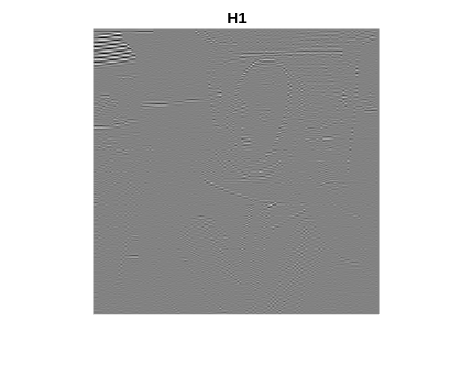

figure, imshow(H1,[]), title('H1');

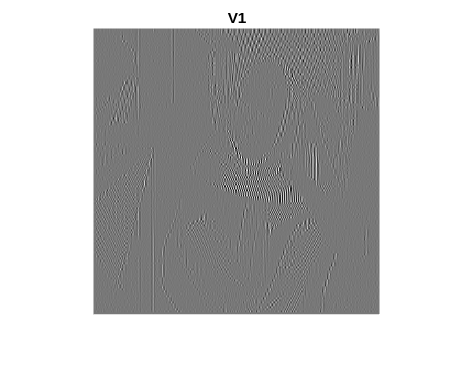

figure, imshow(V1,[]), title('V1');

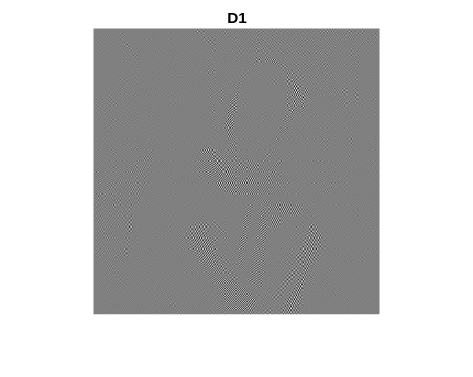

figure, imshow(D1,[]), title('D1');

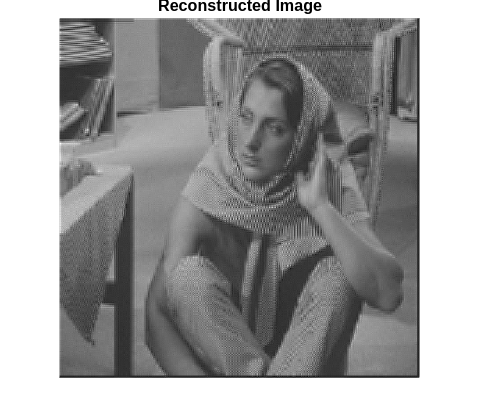


% 6. Reconstruir la imagen con idwt2 y mediante el análisis de multirresolución A1+H1 + V1 + D1
reconstructed_image = idwt2(A1,H1,V1,D1,'db2');

% 7. Visualizar las imágenes reconstruidas
figure, imshow(reconstructed_image,[]), title('Reconstructed Image');


% 8. Guardar la imagen en formato de imagen con imwrite
imwrite(reconstructed_image, 'reconstructed_image.jpg');

# Ejercicio 3. Descomposici´on wavelet de una imagen

#### Crear un script para analizar a nivel superior una imagen (en escala de grises).

#### 1. Cargar una imagen en escala de grises, por ejemplo barb.tif. 

#### 2 Calcular la transformada wavelet de nivel 2 (se har´ıa igual para cualquier nivel) con wavedec2. >> [C,S] = wavedec2(barb,2,’db2’); 

#### 3 Extraer los valores de la tendencia y fluctuaci´on. Ej: >> cA2 = appcoef2(C,S,’db2’,2); >> cH2 = detcoef2(’h’,C,S,2); 4 Observar las variables del espacio de trabajo (workspace). 

#### 5 Reconstruir con waverec2. Visualizar el resultado. 

#### 6 Reconstruir ahora las aproximaciones y los detalles usando, por ejemplo: >> A2 = wrcoef2(’a’,C,S,’db2’,2); >> H1 = wrcoef2(’h’,C,S,’db2’,1); 

#### 7 Visualizar las diferentes matrices. 

#### 8 Recostruirmediantean´alisisdemultiresoluci´on:A2+H2+...+D1.Tratamiento de se˜nales e im´agenes digitales mediante wavelets PRAC

% 1. Cargar una imagen en escala de grises
barb = imread('barb.tif');

% 2. Calcular la transformada wavelet de nivel 2 con wavedec2
[C,S] = wavedec2(barb,2,'db2');

% 3. Extraer los valores de la tendencia y fluctuación
cA2 = appcoef2(C,S,'db2',2);
cH2 = detcoef2('h',C,S,2);

% 4. Observar las variables del espacio de trabajo (workspace)
whos

  Name                        Size                  Bytes  Class     Attributes

  A1                        260x260                540800  double              
  A2                        256x256                524288  double              
  C                           1x67347              538776  double              
  C_dec                       1x266799            2134392  double              
  C_umb                       1x266799            2134392  double              
  D1                        260x260                540800  double              
  Econs                       1x1                       8  double              
  Ew                          1x1                       8  double              
  Ew_values                   1x3                      24  double              
  H1                        260x260                540800  double              
  I_grises                  512x512               2097152  double              
  I_original                512x512    

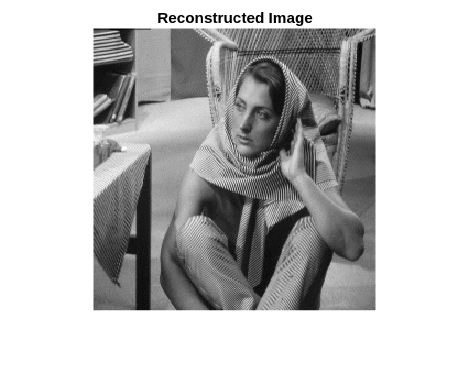


% 5. Reconstruir con waverec2 y visualizar el resultado
reconstructed_image = waverec2(C,S,'db2');
figure, imshow(reconstructed_image,[]), title('Reconstructed Image');

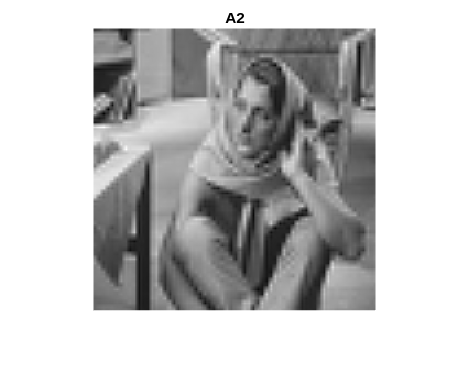


% 6. Reconstruir las aproximaciones y los detalles
A2 = wrcoef2('a',C,S,'db2',2);
H1 = wrcoef2('h',C,S,'db2',1);

% 7. Visualizar las diferentes matrices
figure, imshow(A2,[]), title('A2');

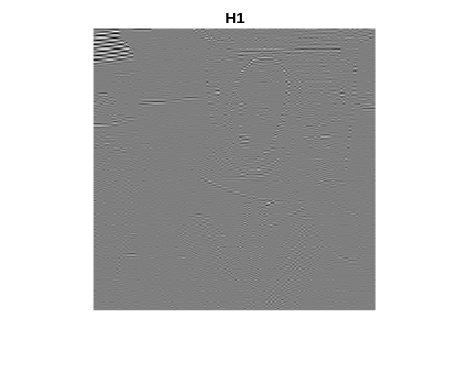

figure, imshow(H1,[]), title('H1');

## Ejercicio 4. Compresi´on de im´agenes

#### Usando el c´odigo anterior comprimir la imagen conservando el 99.99 %, el 99.00 % y el 95.00 % de la energ´ıa. Utilizar diferentes tipos de wavelets y el nivel m´aximo de descomposici´on wavelet

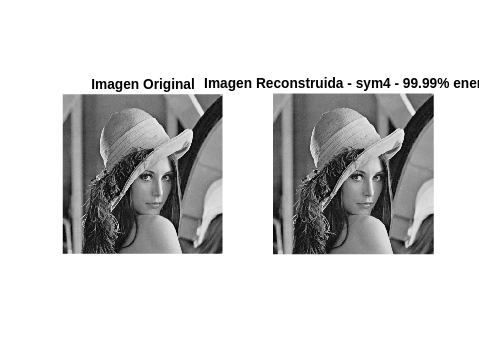

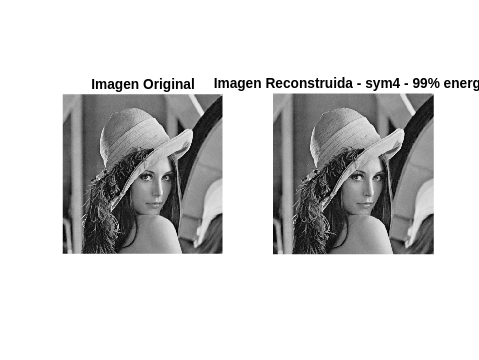

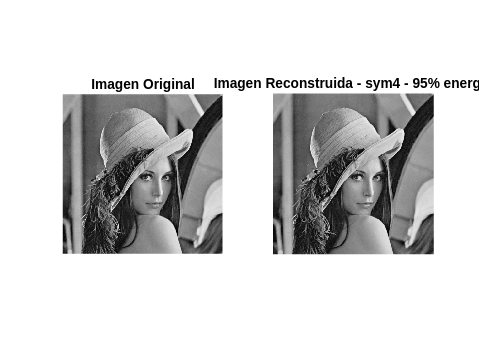

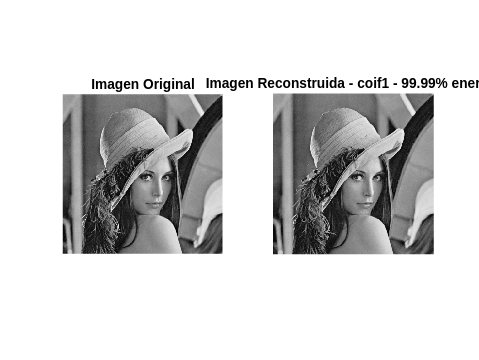

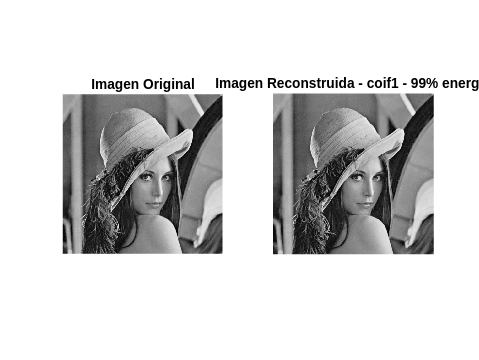

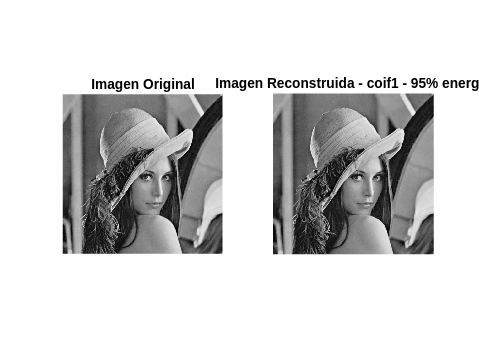

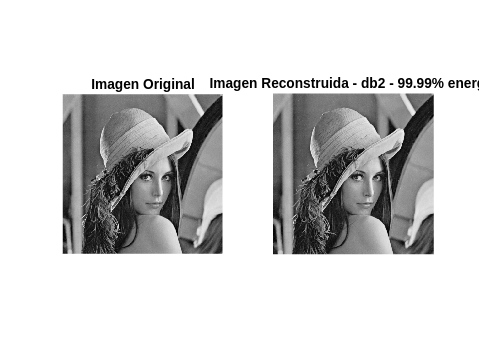

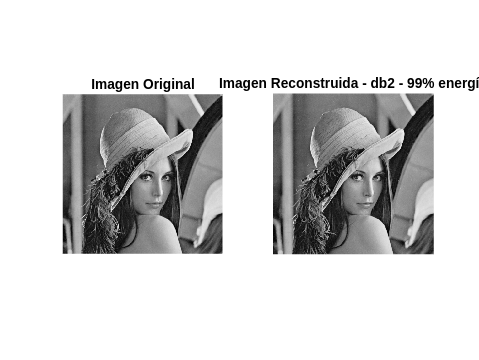

% CARGAMOS ALGUNA IMAGEN DE PRUEBA:
I_original = imread('lena_gr.tif','tif');
I_original = im2double(I_original);

% Parametros.
wavelets = {'sym4', 'coif1', 'db2'}; % Diferentes tipos de wavelets
energy_levels = [0.9999, 0.99, 0.95]; % Niveles de energía a conservar

for i = 1:length(wavelets)
    w = wavelets{i};
    n = wmaxlev(size(I_original),w);
    
    for j = 1:length(energy_levels)
        Econs = energy_levels(j);
        
        [C,L] = wavedec2(I_original,n,w); % Descomposición
        C_dec = sort(abs(C),'descend');
        perfil_energia_C_dec = cumsum(C_dec);
        indice_umbral = find(cumsum(C_dec) >= Econs * perfil_energia_C_dec(end),1);
        umbral = C_dec(indice_umbral); % Valor umbral (threshold).

        % Umbralizado de la transformada
        C_umb = wthresh(C,'h',umbral);
        I_reconstruida = waverec2(C_umb,L,w); % Transformada inversa
        
        % Contar elementos no nulos
        NumNoCeros = nnz(C_umb);
        % Redondeamos el factor:
        RatioCompresion = sprintf('%d:%d', round(length(C)/NumNoCeros), 1);

        figure;
        subplot(1,2,1); imshow(I_original,[]); title('Imagen Original');
        subplot(1,2,2); imshow(I_reconstruida,[min(min(I_original)), max(max(I_original))]); 
        title(['Imagen Reconstruida - ', w, ' - ', num2str(Econs*100), '% energía']);
        subtitle(['Compresión con ', w, ' - ', num2str(Econs*100), '% energía']);
    end
end

## Ejercicio 5. Reducci´on de ruido en im´agenes, wdenoise2

#### Experimentar con el comando wdenoise2 para eliminar ruido en im´agenes.

#### 1. Cargar una imagen, por ejemplo lena gr. 

#### 2 Construir una imagen con ruido; sumando a la anterior un ruido ”blanco, gaussiano¸con randn(n,m): >> s= Imagen(n,m) + factor*randn(n,m) 

#### 3 Reducir el ruido de la magen con wdenoise2, y los par´ametros por defecto. 

#### 4 Representar juntas la imagen original y la de ruido reducido. 

#### 5 Repetir el ejercicio generando im´agenes con distintos niveles de ruido a˜nadido. 

#### 6 Intentar mejorar el resultado modificando alguno de los argumentos de entrada del comando wdenoise2.

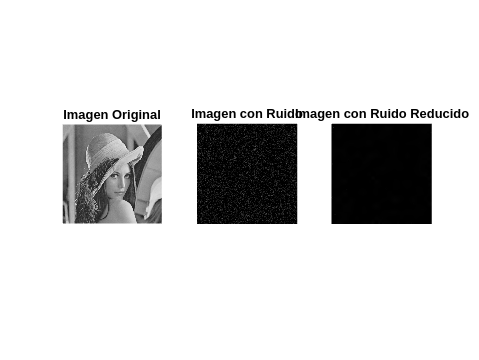

% 1. Cargar una imagen, por ejemplo 'lena' en formato grayscale
img = imread('lena_gr.tif','tif');
img_gray = im2double(I_original);

% 2. Construir una imagen con ruido
[n, m] = size(img_gray);
factor = 25; % Puedes cambiar el factor para distintos niveles de ruido
noisy_img = double(img_gray) + factor * randn(n, m);

% 3. Reducir el ruido de la imagen con wdenoise2, y los parámetros por defecto
denoised_img = wdenoise2(noisy_img);

% 4. Representar juntas la imagen original y la de ruido reducido
figure;
subplot(1, 3, 1);
imshow(img_gray);
title('Imagen Original');

subplot(1, 3, 2);
imshow(uint8(noisy_img));
title('Imagen con Ruido');

subplot(1, 3, 3);
imshow(uint8(denoised_img));
title('Imagen con Ruido Reducido');

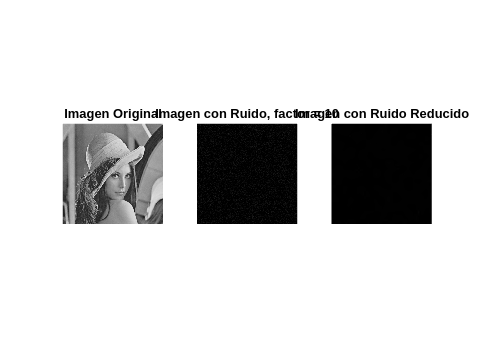

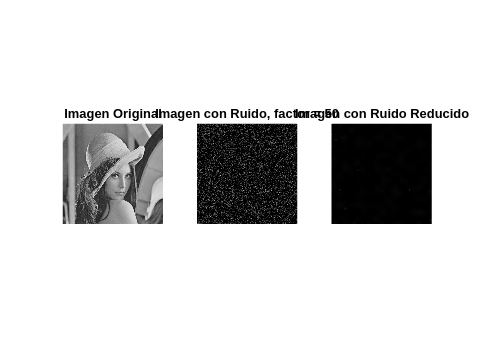

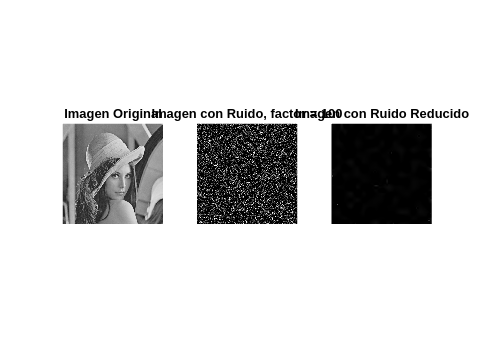


% 5. Repetir el ejercicio generando imágenes con distintos niveles de ruido añadido
factors = [10, 50, 100];
for i = 1:length(factors)
    noisy_img = double(img_gray) + factors(i) * randn(n, m);
    denoised_img = wdenoise2(noisy_img);
    
    figure;
    subplot(1, 3, 1);
    imshow(img_gray);
    title('Imagen Original');
    
    subplot(1, 3, 2);
    imshow(uint8(noisy_img));
    title(['Imagen con Ruido, factor = ', num2str(factors(i))]);
    
    subplot(1, 3, 3);
    imshow(uint8(denoised_img));
    title('Imagen con Ruido Reducido');
end

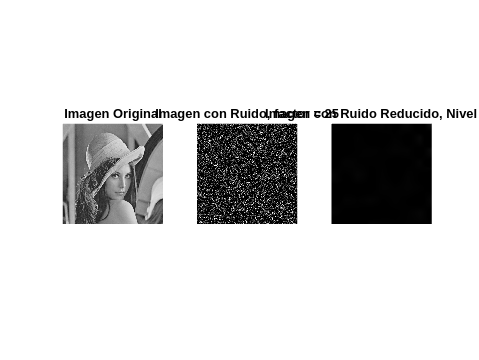


% 6. Intentar mejorar el resultado modificando alguno de los argumentos de entrada del comando wdenoise2
% Por ejemplo, cambiar el nivel de descomposición
levels = 3; % Cambiar el nivel de descomposición
denoised_img = wdenoise2(noisy_img, 'DenoisingMethod', 'UniversalThreshold', 'Wavelet', 'sym4');

figure;
subplot(1, 3, 1);
imshow(img_gray);
title('Imagen Original');

subplot(1, 3, 2);
imshow(uint8(noisy_img));
title(['Imagen con Ruido, factor = ', num2str(factor)]);

subplot(1, 3, 3);
imshow(uint8(denoised_img));
title(['Imagen con Ruido Reducido, Nivel = ', num2str(levels)]);